# beamPropagation2D Example

## Introduction

This script should help you understand the basic concepts and use of the beamPropagation2D object. Hopefully after working through this you will be able to define a field of your interest using the prebuilt definition functions, set appropriate gridding, propagate the object, and plot the results.

Before we get to defining beams and throwing them through space, it is important to take note of the fact that this code is a physical code. In order to get real results you have to stay in a consistent unit basis. For example if we wanted our base distance unit to be meters then a nanometer would be given by 1E-9. As counter intuitive as it may be, working in the units of millimeters balances the scales in the simulation from wavelength to propagation distance and these are the unit for this example

## Create an object and define the gridding

All operations using this code start with the creation of a beamPropagation2D object by calling the constructor of the class

beam = beamPropagation2D() %#ok<*NASGU> 

beam =   beamPropagation2D with properties:

             grid_lambda: []
              grid_xSize: []
              grid_ySize: []
               grid_npts: []
                 grid_dx: []
                 grid_dy: []
              grid_xList: []
              grid_yList: []
                grid_dfx: []
                grid_dfy: []
             grid_fxList: []
             grid_fyList: []
                gauss_Wx: []
                gauss_Wy: []
       gauss_PhaseOffset: []
        gauss_PhaseCurve: []
             laguerre_Wo: []
          laguerre_Modes: []
    laguerre_PhaseOffset: []
     laguerre_PhaseCurve: []
              hermite_Wo: []
           hermite_Modes: []
     hermite_PhaseOffset: []
      hermite_PhaseCurve: []
             input_AperX: []
             input_AperY: []
        input_fileString: []
              rect_NRows: []
              rect_NCols: []
             rect_NBeams: []
        

This call without any parameters creates an empty object that contains references to all of the associated properties but does not define any of them. Notice in this list how each property name is categorized by what the underlying use of it is. For example grid_npts defines the number of computation points in each dimension of the grid.

Now, lets define a beamProp object and initialize the gridding for the simulation. We first need to know a few parameters:

The first is the wavelength of light that you want to use in um

um = 1E-3; 
lambda = 1.55*um;

Next is real space extent of the computational grid in the transverse horizontal and verticle directions in mm. A good rule of thumb is between 5 and 10 times the features of the field you use.

xSize = 40;
ySize = 40;

Finally is the number of computational points as a power of 2. The resulting grid is 2^n by 2^n in size so using too large a power of two will drain the memory in your computer very quick. In general 2^10 is fast and captures detials well.

npts = 2^10;

Now that all of those values are defined we can feed them into the constructor in the order beamPropagation2D( lambda, xSize, ySize, npts )

beam = beamPropagation2D( lambda, xSize, ySize, npts )

beam =   beamPropagation2D with properties:

             grid_lambda: 0.0016
              grid_xSize: 40
              grid_ySize: 40
               grid_npts: 1024
                 grid_dx: 0.0391
                 grid_dy: 0.0391
              grid_xList: [-20 -19.9609 -19.9219 -19.8828 -19.8438 -19.8047 -19.7656 -19.7266 -19.6875 -19.6484 -19.6094 -19.5703 -19.5312 -19.4922 -19.4531 -19.4141 -19.3750 -19.3359 -19.2969 -19.2578 -19.2188 -19.1797 -19.1406 … ] (1×1024 double)
              grid_yList: [-20 -19.9609 -19.9219 -19.8828 -19.8438 -19.8047 -19.7656 -19.7266 -19.6875 -19.6484 -19.6094 -19.5703 -19.5312 -19.4922 -19.4531 -19.4141 -19.3750 -19.3359 -19.2969 -19.2578 -19.2188 -19.1797 -19.1406 … ] (1×1024 double)
                grid_dfx: 0.0250
                grid_dfy: 0.0250
             grid_fxList: [-12.8000 -12.7750 -12.7500 -12.7250 -12.7000 -12.6750 -12.6500 -12.6250 -12.6000 -12.5750 -12.5500 

Notice now how all of the grid_ properties are set in addition to the field_fList (which is just complex zeros at this point).

## Define and view the field 

Within this class there are a number of functions you can call to define unique types of fields. They are Gaussian, Laguerre-Gaussian, Hermite-Gaussian, Hexagonal tiling, Rectangular tiling, and Manual tiling. Each beam type (except Manual) has it's own GUI to help in definition with some initial values. Go ahead and choose one type now. Feel free to change values.

disp('beam.hex_InitialBeamDef2D()'); beam.hex_InitialBeamDef2D(); beam

beam.hex_InitialBeamDef2D()


beam =   beamPropagation2D with properties:

             grid_lambda: 0.0016
              grid_xSize: 40
              grid_ySize: 40
               grid_npts: 1024
                 grid_dx: 0.0391
                 grid_dy: 0.0391
              grid_xList: [-20 -19.9609 -19.9219 -19.8828 -19.8438 -19.8047 -19.7656 -19.7266 -19.6875 -19.6484 -19.6094 -19.5703 -19.5312 -19.4922 -19.4531 -19.4141 -19.3750 -19.3359 -19.2969 -19.2578 -19.2188 -19.1797 -19.1406 … ] (1×1024 double)
              grid_yList: [-20 -19.9609 -19.9219 -19.8828 -19.8438 -19.8047 -19.7656 -19.7266 -19.6875 -19.6484 -19.6094 -19.5703 -19.5312 -19.4922 -19.4531 -19.4141 -19.3750 -19.3359 -19.2969 -19.2578 -19.2188 -19.1797 -19.1406 … ] (1×1024 double)
                grid_dfx: 0.0250
                grid_dfy: 0.0250
             grid_fxList: [-12.8000 -12.7750 -12.7500 -12.7250 -12.7000 -12.6750 -12.6500 -12.6250 -12.6000 -12.5750 -12.5500 

Notice how the related properties of the update while all of the others remain undefined. If you re-run this with a different type then the properties for BOTH types will be defined even though the field is the last used. Normally you would recreate the object which would clear properties between field definitions.

To view the field there is the function plotField2D. This function takes one of the two strings, 'abs' to view intesity or 'angle' to view wavefront phase

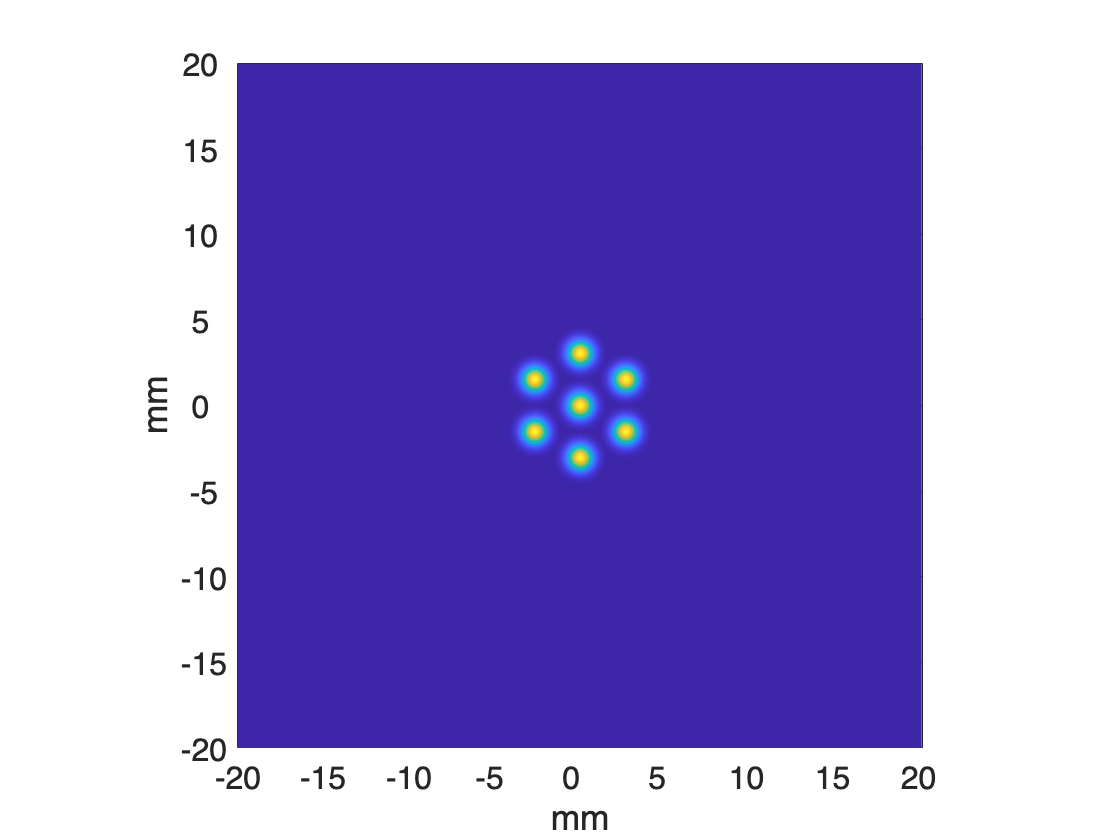

beam.plotField2D('abs')

## Propagate the beam

The last bit to this code is propagating the beam into the far field using the function forwardProp_FreeSpace(z). The only restiction being that is distance must be significanly greater than the wavelength you chose. This function also returns the propagated field *without* setting the object field property to this new field. This is so you can use a single beam and propagate it many times without redefinition. Additionally the plotField2D function accepts two input where the second is the field to be ploted instead of the intenally defined field.

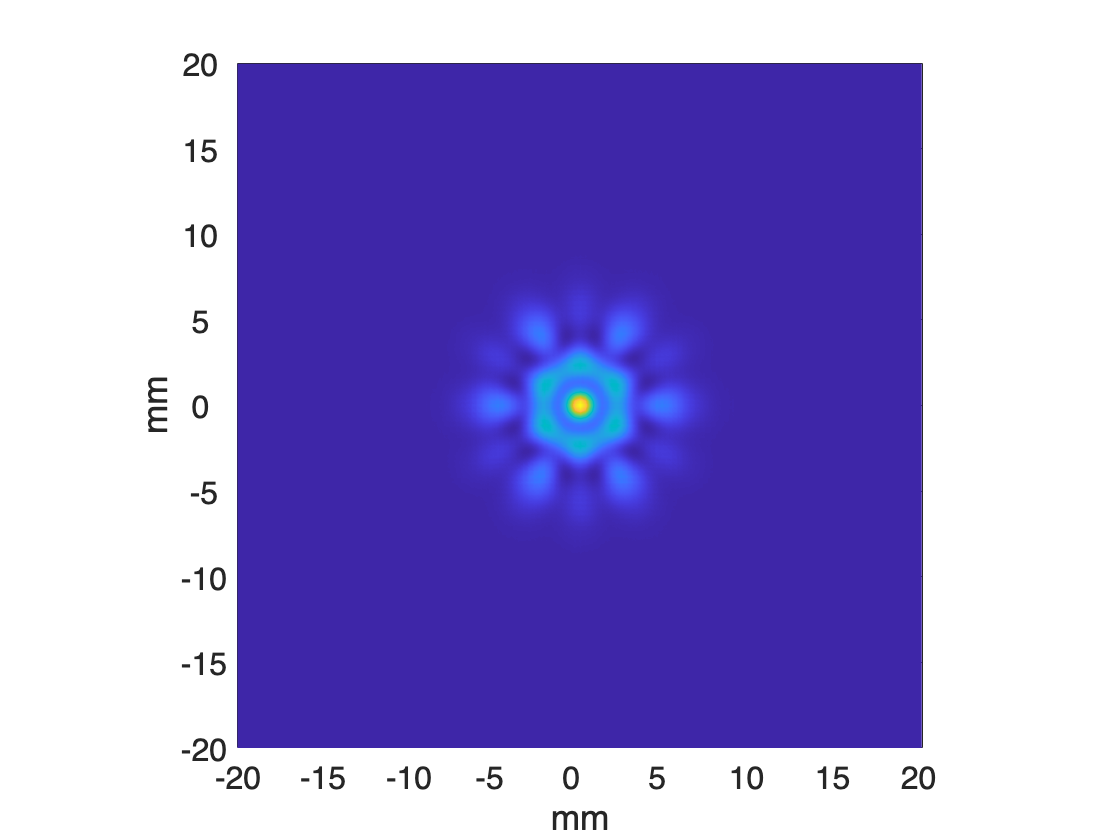

m = 1E3;
propBeam = beam.forwardProp_FreeSpace2D(8*m);
beam.plotField2D('abs',propBeam)

## Putting it all together

You can also put together the first few section into one line of code. The field definition functions can be called from the constructor for the class by adding a string into the fifth input varible. The accepted values are: 'gauss', 'laguerre, 'hermite', 'hex', 'rect', and 'man.

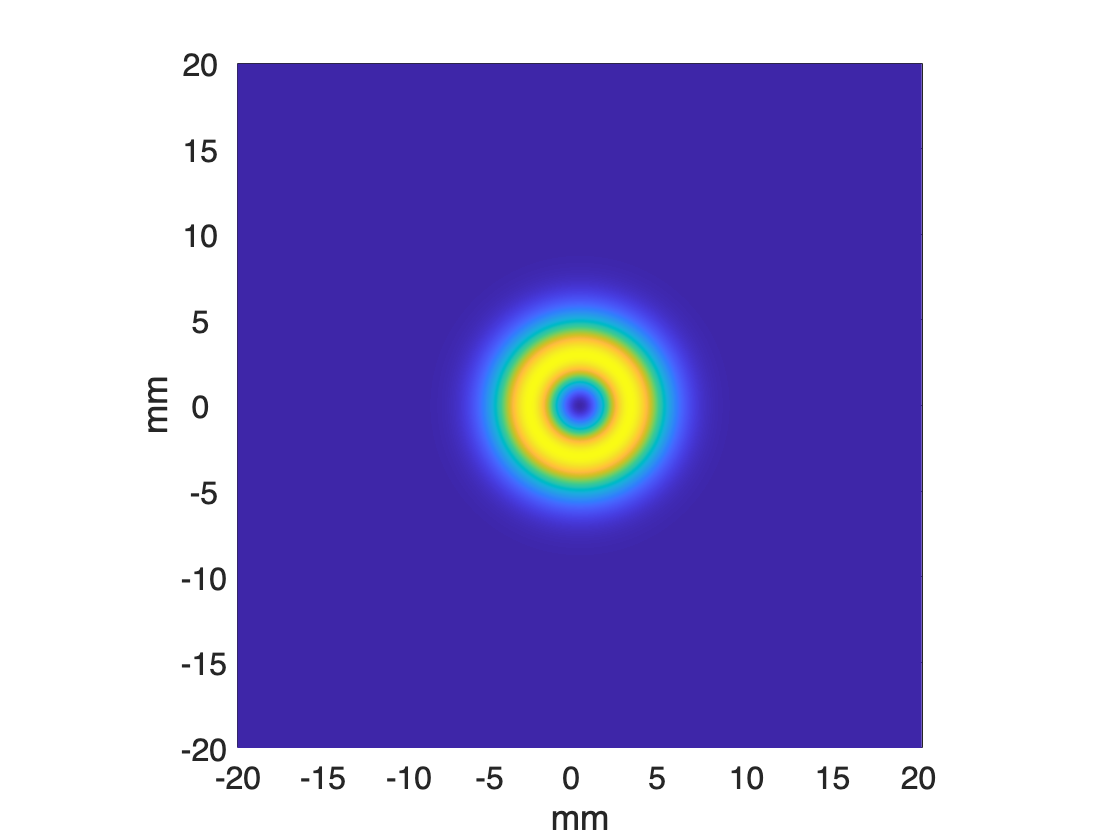

beam = beamPropagation2D(lambda,xSize,ySize,npts,'laguerre');
newBeam = beam.forwardProp_FreeSpace2D(10*m);
figure(1)
beam.plotField2D('abs',newBeam);

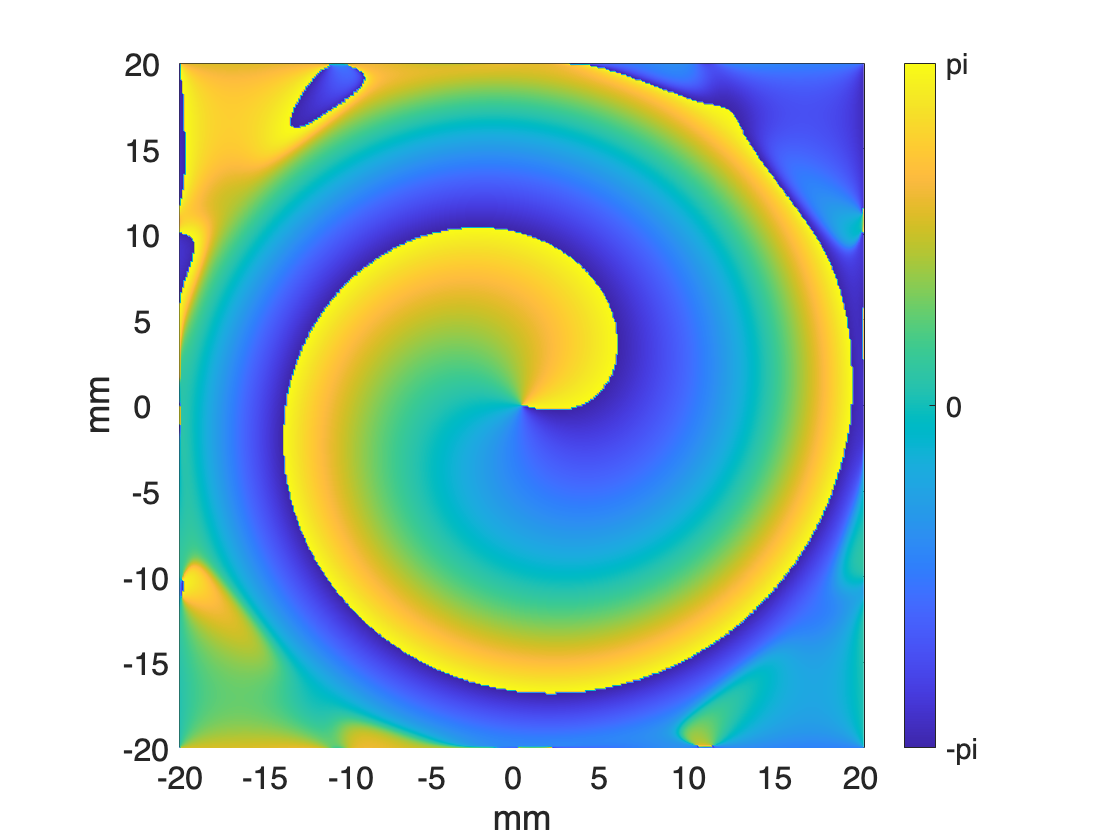

figure(2)
beam.plotField2D('angle',newBeam);